clear;
clc;
run = load("HalfLekaSlippingonMatsRaibert1.mat");

tStart = 19270; %ms
tEnd = 32490; %ms - somewhat through last flight
dy = timeseries2timetable(run.data{9}.Values.dy);

y = timeseries2timetable(run.data{9}.Values.y);

dx = timeseries2timetable(run.data{9}.Values.dx);


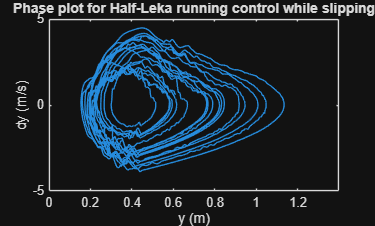


% Final plots
plot(y.y(tStart:tEnd),dy.dy(tStart:tEnd));
hold on
xlabel("y (m)")
ylabel("dy (m/s)")
title("Phase plot for Half-Leka running control while slipping")
axis([0 1.4 -5 5])
hold off

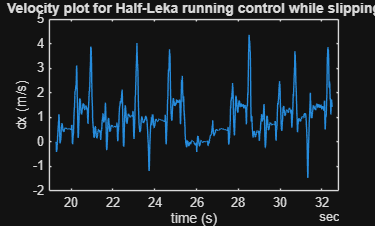


plot(dx.Time(tStart:tEnd), dx.dx(tStart:tEnd))
hold on
xlabel("time (s)")
ylabel("dx (m/s)")
title("Velocity plot for Half-Leka running control while slipping")
hold off